# Reproducing the numerical experiments for OR-ANOVA

This live script collects the main numerical evidence in the order used in the paper. It does not replace the unit tests or the dataset scripts. Instead, it calls the existing implementation through a single, reproducible workflow.

clear; clc; close all;

live_script_file = matlab.desktop.editor.getActiveFilename;
addpath(fullfile(fileparts(live_script_file), 'core'));
project_root = set_path();

Project path is ready.



seed = 1;
rng(seed);

## 1. Fast ANOVA via the FFT

The FFT implementation and recursive ANOVA compute the same orthogonal projection. We first check their numerical agreement and then compare their running times. Random tensors are appropriate here because this is an implementation check rather than a model-approximation experiment.

accuracy_configs = [
    5, 4, 1;
    5, 4, 2;
    6, 3, 1;
    6, 3, 2;
    7, 2, 3;
    7, 3, 2;
    8, 2, 4;
    8, 3, 3;
    9, 3, 2;
    10, 2, 4
];

num_accuracy_tests = size(accuracy_configs, 1);
accuracy_results = table('Size', [num_accuracy_tests, 5], ...
    'VariableTypes', repmat({'double'}, 1, 5), ...
    'VariableNames', {'d', 'n', 's', 'N', 'relative_difference'});

for k = 1:num_accuracy_tests
    d = accuracy_configs(k, 1); % Tensor order
    n = accuracy_configs(k, 2); % Mode size along each dimension
    s = accuracy_configs(k, 3); % interaction order
    g = randn(n * ones(1, d));

    f_fast = cluster_expansion(g, s);
    f_recursive = recursive_anova_projection(g, s); % See at the end, defined as local function

    accuracy_results{k, :} = [d, n, s, numel(g), ...
        norm(f_fast(:) - f_recursive(:)) / ...
        max(norm(f_recursive(:)), eps)];
end

disp(accuracy_results);

    d     n    s      N      relative_difference
    __    _    _    _____    ___________________

     5    4    1     1024        3.0878e-16     
     5    4    2     1024        3.6399e-16     
     6    3    1      729        3.8102e-16     
     6    3    2      729        4.6271e-16     
     7    2    3      128        6.7832e-16     
     7    3    2     2187        5.7243e-16     
     8    2    4      256        1.1557e-15     
     8    3    3     6561        9.0757e-16     
     9    3    2    19683        6.0259e-16     
    10    2    4     1024        2.1924e-15     



## 1.1 Scaling comparison

We plot running time against tensor order d. Since both methods scale roughly with N = n^d, we also plot time per tensor entry on a linear vertical axis.

n_scaling = 4; % mode size for scaling experiments
s_scaling = 2;
d_list = 5:12;
num_scaling_tests = numel(d_list);

scaling_results = table('Size', [num_scaling_tests, 7], ...
    'VariableTypes', repmat({'double'}, 1, 7), ...
    'VariableNames', {'d', 'n', 's', 'N', 'fast_seconds', ...
    'recursive_seconds', 'speedup'});

for k = 1:num_scaling_tests
    d = d_list(k);
    g = randn(n_scaling * ones(1, d));

    fast_seconds = timeit(@() cluster_expansion(g, s_scaling));
    recursive_seconds = timeit(@() recursive_anova_projection(g, s_scaling));

    scaling_results{k, :} = [d, n_scaling, s_scaling, numel(g), ...
        fast_seconds, recursive_seconds, recursive_seconds / fast_seconds];
end

disp(scaling_results);

    d     n    s        N         fast_seconds    recursive_seconds    speedup
    __    _    _    __________    ____________    _________________    _______

     5    4    2          1024     0.00012789        0.00068834        5.3824 
     6    4    2          4096     0.00022719         0.0015584        6.8594 
     7    4    2         16384      0.0010341         0.0063991        6.1883 
     8    4    2         65536      0.0050865          0.010934        2.1497 
     9    4    2    2.6214e+05        0.01973            0.0589        2.9854 
    10    4    2    1.0486e+06        0.09356           0.19574        2.0921 
    11    4    2    4.1943e+06        0.54328            1.3482        2.4816 
    12    4    2    1.6777e+07         2.3032     

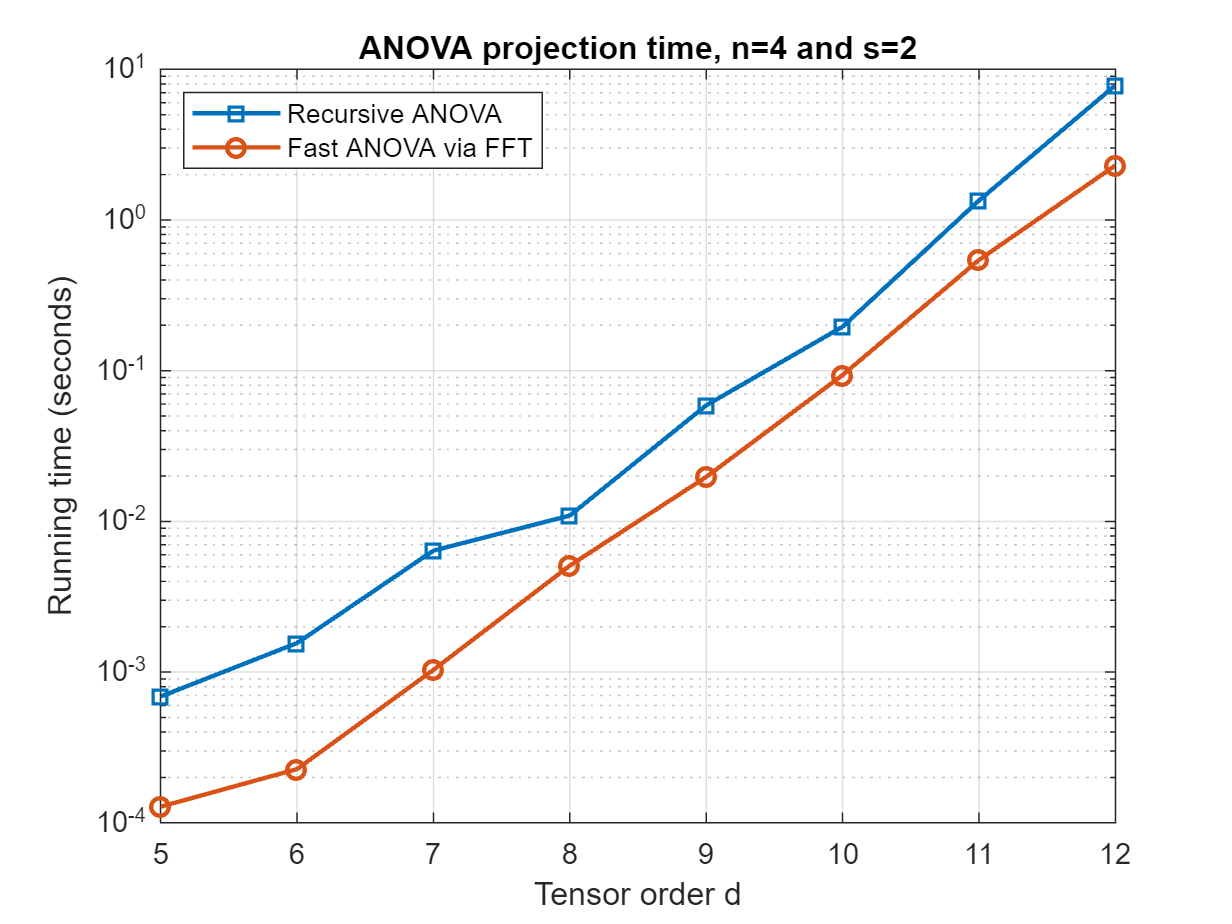

% Plot runtime against tensor order.
figure('Name', 'Fast ANOVA scaling');
semilogy(scaling_results.d, scaling_results.recursive_seconds, '-s', ...
    'LineWidth', 1.5, 'DisplayName', 'Recursive ANOVA');
hold on;
semilogy(scaling_results.d, scaling_results.fast_seconds, '-o', ...
    'LineWidth', 1.5, 'DisplayName', 'Fast ANOVA via FFT');
hold off;
grid on;
xlabel('Tensor order d');
ylabel('Running time (seconds)');
title(sprintf('ANOVA projection time, n=%d and s=%d', n_scaling, s_scaling));
legend('Location', 'northwest');

## 2. Global and local recovery of Sobol's example

This synthetic-data experiment uses Sobol's product test function, with two important variables and six less important variables,

where a_1 = a_2 = 0 and a_3 = ... = a_8 = 3. The function is sampled on a modest full tensor grid so that it remains compatible with the current FFT implementation.

rng(seed + 1);
d = 8;
n = 3; % number of discretization points along each variable
sz = n * ones(1, d);
a = [0, 0, 3 * ones(1, d - 2)];

% Sample Sobol's product function on the full tensor grid.
grid_points = (0:n-1)' / n;
x_true = ones(sz);
for j = 1:d
    g_j = (abs(4 * grid_points - 2) + a(j)) / (1 + a(j));
    factor_shape = ones(1, d);
    factor_shape(j) = n;
    x_true = x_true .* reshape(g_j, factor_shape);
end
x_true = x_true(:);

We observe approximately 30% of the Sobol tensor entries and add Gaussian noise scaled to norm eta, equal to 1% of the clean observation norm. Global and local recovery use the same sampling operator and noisy data.

N = prod(sz); % ambient dimension
rho = 0.30; % observation ratio
M = round(rho * N); % number of observations
sampling_rate = M / N;

% Draw observed entries and add noise.
observed_idx = randperm(N, M);
unobserved_idx = setdiff(1:N, observed_idx);
S = sparse(1:M, observed_idx, 1, M, N);

clean_data = S * x_true;
noise = randn(M, 1);
eta = 0.01 * norm(clean_data);
noise = eta * noise / max(norm(noise), eps);
y = clean_data + noise;

## 2.1 Choosing the interaction order

Sobol's example and Owen's ANOVA analysis motivate a low interaction order, but they do not prescribe the cutoff for this discretized tensor. We therefore compare the relative L2 approximation errors and choose interaction order from the numerical test below.

interaction_orders = (0:4)';
relative_L2_error = zeros(size(interaction_orders));

for k = 1:numel(interaction_orders)
    approximation = cluster_expansion( ...
        x_true, interaction_orders(k), sz);
    relative_L2_error(k) = norm(x_true - approximation) / norm(x_true);
end

order_results = table(interaction_orders, relative_L2_error);
disp(order_results);

    interaction_orders    relative_L2_error
    __________________    _________________

            0                   0.70737    
            1                   0.33248    
            2                   0.10218    
            3                  0.022759    
            4                 0.0038426    



Therefore, we choose the interaction order s = 3

s = 3;
approximation_error = relative_L2_error(interaction_orders == s);
fprintf('We use s=%d, with relative L2 approximation error %.1f%%.\n', ...
    s, approximation_error*100)

We use s=3, with relative L2 approximation error 2.3%.


## 2.2 Global recovery

We first recover the Sobol tensor from the shared observations. In this setting, any admissible value of tau defines a globally optimal recovery map, so we use tau = 0.5. Recovery is evaluated by relative L2 error over the full tensor and separately over the unobserved entries.

% Recover with a fixed regularization parameter.
tau = 0.5;
global_timer = tic;
[global_recovery, global_info] = regularized_solution( ...
    S, y, s, tau, sz, false);
global_total_time = toc(global_timer);

% Evaluate full-grid and unobserved-entry errors.
global_relative_L2_error = norm(global_recovery - x_true) / ...
    max(norm(x_true), eps);
global_unobserved_relative_L2_error = ...
    norm(global_recovery(unobserved_idx) - x_true(unobserved_idx)) / ...
    max(norm(x_true(unobserved_idx)), eps);

global_result = table(N, M, sampling_rate, ...
    s, global_info.r, tau, ...
    global_relative_L2_error, ...
    global_unobserved_relative_L2_error, global_total_time, ...
    'VariableNames', {'N', 'M', 'sampling_rate', 's', 'model_dimension', ...
    'tau', 'relative_L2_error', 'unobserved_relative_L2_error', ...
    'total_time'});

disp(global_result(:, ...
    {'N', 'M', 's', 'relative_L2_error', ...
     'unobserved_relative_L2_error', 'total_time'}))

     N       M      s    relative_L2_error    unobserved_relative_L2_error    total_time
    ____    ____    _    _________________    ____________________________    __________

    6561    1968    3        0.025439                   0.029301               0.091668 



Since SS* = I, the minimal global worst-case error (gwce) equals the optimal local worst-case error (lwce) at y = 0 (Foucart and Liao, 2023). We compute gwce by solving the local recovery problem with y = 0 and evaluating its lwce formula. Because the true tensor is known, the relative worst-case error is that error divided by norm(x_true).

P_V_perp = @(x) x - cluster_expansion(x, s, sz);
epsilon_actual = norm(P_V_perp(x_true));
bound_inflation = 1.10;
epsilon_bound = bound_inflation * epsilon_actual;
eta_bound = bound_inflation * eta;

% Use practical power settings to avoid underflow at the theoretical iteration count.
sobol_num_samples = 100;
sobol_power_iter = 20000;
power_options = struct('method', 'sextic', ...
    'eigenvalue_method', 'power', ...
    'num_samples', sobol_num_samples, 'power_iter', sobol_power_iter);
svd_options = struct('method', 'sextic', 'eigenvalue_method', 'svd');

rng(seed + 200);
% Estimate the smallest eigenvalue by power iteration, then solve the sextic equation.
timer = tic;
[gwce_power, zero_power_info] = compute_gwce( ...
    S, s, sz, epsilon_bound, eta_bound, power_options);
power_time = toc(timer);

% Compute the smallest eigenvalue by SVD, then solve the sextic equation.
timer = tic;
[gwce_svd, zero_svd_info] = compute_gwce( ...
    S, s, sz, epsilon_bound, eta_bound, svd_options);
svd_time = toc(timer);

spectral_comparison = table(["Power"; "SVD"], ...
    [zero_power_info.lambda_test; zero_svd_info.lambda_test], ...
    [zero_power_info.tau_zero; zero_svd_info.tau_zero], ...
    [gwce_power; gwce_svd], ...
    [gwce_power; gwce_svd] / norm(x_true), ...
    [power_time; svd_time], ...
    'VariableNames', {'eigenvalue_method', 'lambda_test', ...
    'tau_zero', 'gwce', 'relative_worst_case_error', 'seconds'});
disp(spectral_comparison);

    eigenvalue_method    lambda_test    tau_zero     gwce     relative_worst_case_error    seconds
    _________________    ___________    ________    ______    _________________________    _______

         "Power"           0.01404      0.80512     20.009             0.11999             1262.3 
         "SVD"             0.01412       0.8051     19.953             0.11965             19.255 



Therefore, the power method works well in estimating optimal parameter and lwce. More tests on the power method can be found at tests\tests_optimal_param.

## 2.3 Local recovery from the local worst-case-error viewpoint

The local map uses the sextic parameter at the observed data, with the same bounds and power-method settings as above.

% Use the same power-method settings for the local parameter.
local_options = power_options;
timer = tic;
[tau_local, local_parameter_info] = solve_opt_param( ...
    S, y, s, sz, epsilon_bound, eta_bound, local_options);
parameter_time = toc(timer);

timer = tic;
[local_recovery, local_info] = regularized_solution( ...
    S, y, s, tau_local, sz, false);
recovery_time = toc(timer);

local_relative_L2_error = norm(local_recovery - x_true) / ...
    max(norm(x_true), eps);
local_unobserved_relative_L2_error = ...
    norm(local_recovery(unobserved_idx) - x_true(unobserved_idx)) / ...
    max(norm(x_true(unobserved_idx)), eps);

local_lwce = sqrt(local_parameter_info.lwce_sq);
local_result = table(tau_local, local_lwce, ...
    local_lwce / norm(x_true), ...
    local_relative_L2_error, ...
    local_unobserved_relative_L2_error, ...
    parameter_time, recovery_time, ...
    'VariableNames', {'tau', 'lwce', 'relative_worst_case_error', 'relative_L2_error', ...
    'unobserved_relative_L2_error', 'parameter_time', 'recovery_time'});
disp(local_result);

      tau       lwce     relative_worst_case_error    relative_L2_error    unobserved_relative_L2_error    parameter_time    recovery_time
    _______    ______    _________________________    _________________    ____________________________    ______________    _____________

    0.80556    18.633             0.11174                 0.025177                   0.029301                  1155.7          0.038492   



## 3. Global and local recovery of the Energy Efficiency dataset

The Energy Efficiency dataset contains 768 simulated building configurations. Its inputs describe geometry, orientation, and glazing; Y1 is heating load and Y2 is cooling load. We first check for redundant geometry variables before constructing the tensor.

energy_file = fullfile(project_root, 'datasets', 'energy_efficiency', ...
    'data_set', 'ENB2012_data.xlsx');
energy_table = readtable(energy_file, 'VariableNamingRule', 'preserve');

The five geometry variables X1–X5 describe compactness, surface area, wall area, roof area, and height. We count the distinct geometry tuples and the distinct values of X1.

geometry = energy_table{:, {'X1', 'X2', 'X3', 'X4', 'X5'}};
num_geometries = size(unique(geometry, 'rows'), 1);
num_x1_values = numel(unique(energy_table.X1));
fprintf('Unique X1 values: %d; unique geometries: %d; one geometry per X1: %s\n', ...
    num_x1_values, num_geometries, ...
    mat2str(num_x1_values == num_geometries));

Unique X1 values: 12; unique geometries: 12; one geometry per X1: true


Both counts are 12. Because X1 is part of each geometry tuple, this equality means every observed X1 value determines exactly one geometry. We therefore keep X1 and omit the redundant X2–X5 variables.

X1 identifies building geometry, and X6 records orientation. X7 gives glazing area and X8 its distribution. We encode each of the 16 observed (X7, X8) pairs as one glazing category. The tensor therefore has three axes: geometry, orientation, and glazing configuration; interaction order refers to these axes.

energy_response_names = {'Y1', 'Y2'};
energy_Y = energy_table{:, energy_response_names};

% X1 indexes geometry; observed (X7, X8) pairs index glazing.
[x1_levels, ~, x1_index] = unique(energy_table.X1, 'stable');
[x6_levels, ~, x6_index] = unique(energy_table.X6, 'stable');
[glazing_levels, ~, glazing_index] = unique( ...
    energy_table{:, {'X7', 'X8'}}, 'rows', 'stable');
fprintf('Observed glazing configurations: %d\n', size(glazing_levels, 1));

Observed glazing configurations: 16



sz_energy = [numel(x1_levels), numel(x6_levels), size(glazing_levels, 1)];
energy_cell_index = sub2ind(sz_energy, ...
    x1_index, x6_index, glazing_index);
N_energy = prod(sz_energy);
energy_cell_count = accumarray(energy_cell_index, 1, [N_energy, 1]);
energy_tensor = zeros(numel(energy_response_names), N_energy);
for j = 1:numel(energy_response_names)
    energy_tensor(j, :) = accumarray(energy_cell_index, energy_Y(:, j), ...
        [N_energy, 1], @mean, 0).';
end

energy_active_cells = find(energy_cell_count > 0);
fprintf('Energy tensor: [%s], active cells: %d/%d\n', ...
    num2str(sz_energy), numel(energy_active_cells), N_energy);

Energy tensor: [12   4  16], active cells: 768/768


We randomly select 70% of the active tensor cells for training and use the remaining 30% for testing. Both responses and recovery methods use the same seeded split.

rng(seed + 1);
energy_cells = energy_active_cells(randperm(numel(energy_active_cells)));
num_energy_training = round(0.7 * numel(energy_cells));
energy_training_cells = energy_cells(1:num_energy_training);
energy_test_cells = energy_cells(num_energy_training + 1:end);
S_energy = sparse(1:num_energy_training, energy_training_cells, ...
    1, num_energy_training, N_energy);

fprintf('Training cells: %d; test cells: %d\n', ...
    numel(energy_training_cells), numel(energy_test_cells));

Training cells: 538; test cells: 230


## 3.1 Choosing the interaction orders

The complete response tensors let us compare the relative ANOVA approximation errors for interaction orders s = 0, 1, 2, and 3.

energy_approx_orders = 0:3;
energy_approx_error = zeros(numel(energy_approx_orders), ...
    numel(energy_response_names));

for j = 1:numel(energy_response_names)
    f = energy_tensor(j, :).';
    for k = 1:numel(energy_approx_orders)
        approximation = cluster_expansion(f, energy_approx_orders(k), sz_energy);
        energy_approx_error(k, j) = ...
            norm(f - approximation) / norm(f);
    end
end

energy_approximation = table(energy_approx_orders(:), ...
    energy_approx_error(:, 1), energy_approx_error(:, 2), ...
    'VariableNames', {'s', 'Y1_error', 'Y2_error'});
disp(energy_approximation);

    s     Y1_error      Y2_error 
    _    __________    __________

    0       0.41191       0.36064
    1      0.040922      0.064641
    2      0.012266      0.048717
    3    2.4956e-16    2.0497e-16



The relative errors at s = 1 and s = 2 are modest, so we retain both orders for recovery. The full third-order model has 768 dimensions, exceeding the 538 training measurements.

energy_orders = [1, 2];

## 3.2 Global recovery

For each response, we use the fixed global parameter tau = 0.5 at interaction orders s = 1 and s = 2. The reconstruction norm provides a scale for the worst-case errors. Test error is computed only on withheld entries.

tau_energy_global = 0.5;
energy_global_rows = cell(numel(energy_response_names) * ...
    numel(energy_orders), 7);
row = 0;

for response_index = 1:numel(energy_response_names)
    target = string(energy_response_names{response_index});
    y_energy = energy_tensor(response_index, energy_training_cells).';
    test_truth = energy_tensor(response_index, energy_test_cells).';

    for s_energy = energy_orders
        timer = tic;
        [recovered, recovery_info] = regularized_solution( ...
            S_energy, y_energy, s_energy, tau_energy_global, sz_energy);
        recovery_time = toc(timer);
        test_error = norm(recovered(energy_test_cells) - test_truth) / ...
            max(norm(test_truth), eps);

        row = row + 1;
        energy_global_rows(row, :) = {target, s_energy, recovery_info.r, ...
            tau_energy_global, test_error, recovery_time, norm(recovered)};
    end
end

energy_global_results = cell2table(energy_global_rows, ...
    'VariableNames', {'target', 's', 'model_dimension', 'tau', ...
    'test_relative_L2_error', 'recovery_time', 'recovery_norm'});
disp(energy_global_results(:, ...
    {'target', 's', 'model_dimension', 'tau', ...
    'test_relative_L2_error', 'recovery_time'}));

    target    s    model_dimension    tau    test_relative_L2_error    recovery_time
    ______    _    _______________    ___    ______________________    _____________

     "Y1"     1           30          0.5           0.039782              0.011931  
     "Y1"     2          273          0.5           0.024844              0.006014  
     "Y2"     1           30          0.5           0.066573              0.015143  
     "Y2"     2          273          0.5           0.087145             0.0033103  



As in the Sobol experiment, we compute gwce through local recovery with y = 0. Guided by the approximation errors in Section 3.1, we set the mismatch bound to 5% and 2% of the corresponding global reconstruction norm for Y1 at s = 1, 2, and to 8% and 6% for Y2. In each case, we assume a noise bound of 3% of the training-observation norm. We hold these bounds fixed when computing gwce at y = 0. Here the relative-error entry beside each gwce or lwce is that error divided by the norm of the corresponding true tensor.

% Rows: Y1 at s = 1, 2; Y2 at s = 1, 2.
energy_cases = table( ...
    ["Y1"; "Y1"; "Y2"; "Y2"], ...
    [1; 2; 1; 2], ...
    [0.05; 0.02; 0.08; 0.06], ...
    0.03 * ones(4, 1), ...
    'VariableNames', {'target', 's', 'mismatch_rel', 'noise_rel'});

energy_cases.epsilon_bound = zeros(height(energy_cases), 1);
energy_cases.eta_bound = zeros(height(energy_cases), 1);
energy_cases.gwce = zeros(height(energy_cases), 1);

rng(seed + 4);
% s = 1 needs fewer iterations to avoid underflow.
energy_power_iter = [4000, 10000];
energy_options = struct('method', 'sextic', ...
    'eigenvalue_method', 'power', 'num_samples', 100);

for k = 1:height(energy_cases)
    target = energy_cases.target(k);
    s_energy = energy_cases.s(k);
    response_index = find(strcmp(energy_response_names, target), 1);
    global_index = find(energy_global_results.target == target & ...
        energy_global_results.s == s_energy);
    y_energy = energy_tensor(response_index, energy_training_cells).';

    energy_cases.epsilon_bound(k) = energy_cases.mismatch_rel(k) * ...
        energy_global_results.recovery_norm(global_index);
    energy_cases.eta_bound(k) = energy_cases.noise_rel(k) * norm(y_energy);

    case_options = energy_options;
    case_options.power_iter = energy_power_iter(s_energy);
    % gwce is the local worst-case error at y = 0 with these fixed bounds.
    [energy_cases.gwce(k), ~] = compute_gwce( ...
        S_energy, s_energy, sz_energy, ...
        energy_cases.epsilon_bound(k), energy_cases.eta_bound(k), case_options);
end

for k = 1:height(energy_global_results)
    case_index = find(energy_cases.target == energy_global_results.target(k) & ...
        energy_cases.s == energy_global_results.s(k));
    energy_global_results.gwce(k) = energy_cases.gwce(case_index);
end
energy_global_results.relative_worst_case_error = zeros(height(energy_global_results), 1);
for k = 1:height(energy_global_results)
    response_index = find(strcmp(energy_response_names, ...
        energy_global_results.target(k)), 1);
    energy_global_results.relative_worst_case_error(k) = ...
        energy_global_results.gwce(k) / norm(energy_tensor(response_index, :));
end
disp(energy_global_results(:, ...
    {'target', 's', 'test_relative_L2_error', 'gwce', 'relative_worst_case_error'}));

    target    s    test_relative_L2_error     gwce     relative_worst_case_error
    ______    _    ______________________    ______    _________________________

     "Y1"     1           0.039782           64.802             0.09552         
     "Y1"     2           0.024844           105.86             0.15603         
     "Y2"     1           0.066573           99.095             0.13564         
     "Y2"     2           0.087145           215.37              0.2948         



## 3.3 Local recovery 

For each response, we use s = 1 and s = 2, the bounds above, and solve a sextic equation to find the local optimal parameters.

local_cases = energy_cases;
energy_local_rows = cell(height(local_cases), 9);
energy_local_diagnostics = cell(height(local_cases), 1);

for k = 1:height(local_cases)
    target = local_cases.target(k);
    s_energy = local_cases.s(k);
    response_index = find(strcmp(energy_response_names, target), 1);
    y_energy = energy_tensor(response_index, energy_training_cells).';
    test_truth = energy_tensor(response_index, energy_test_cells).';

    case_options = energy_options;
    case_options.power_iter = energy_power_iter(s_energy);
    timer = tic;
    [tau_local, parameter_info] = solve_opt_param( ...
        S_energy, y_energy, s_energy, sz_energy, ...
        local_cases.epsilon_bound(k), local_cases.eta_bound(k), case_options);
    parameter_time = toc(timer);

    timer = tic;
    [recovered, recovery_info] = regularized_solution( ...
        S_energy, y_energy, s_energy, tau_local, sz_energy);
    recovery_time = toc(timer);
    test_error = norm(recovered(energy_test_cells) - test_truth) / ...
        max(norm(test_truth), eps);

    lwce = sqrt(parameter_info.lwce_sq);
    energy_local_rows(k, :) = {target, s_energy, recovery_info.r, ...
        tau_local, lwce, lwce / norm(energy_tensor(response_index, :)), ...
        test_error, ...
        parameter_time, recovery_time};
    energy_local_diagnostics{k} = parameter_info;
end

energy_local_results = cell2table(energy_local_rows, ...
    'VariableNames', {'target', 's', 'model_dimension', 'tau', ...
    'lwce', 'relative_worst_case_error', 'test_relative_L2_error', 'parameter_time', 'recovery_time'});
disp(energy_local_results);

    target    s    model_dimension      tau       lwce     relative_worst_case_error    test_relative_L2_error    parameter_time    recovery_time
    ______    _    _______________    _______    ______    _________________________    ______________________    ______________    _____________

     "Y1"     1           30          0.64254     57.34             0.08452                    0.039782               23.031          0.0018497  
     "Y1"     2          273          0.44415    104.26             0.15368                    0.024844                57.53          0.0025313  
     "Y2"     1           30          0.73307     84.95             0.11628                    0.066573      

## 3.4 Global and local comparison

We compare global and local recovery for each response at the same order and train/test split. The worst_case_error column gives gwce for global recovery and lwce for local recovery; both are absolute full-tensor errors under the assumed bounds. Testing relative error is measured on withheld entries and has a different denominator. At a fixed order, both methods have the same test error because changing tau affects only observed cells.

global_comparison = energy_global_results(:, ...
    {'target', 's', 'tau', 'gwce', 'relative_worst_case_error', ...
    'test_relative_L2_error', 'recovery_time'});
global_comparison = renamevars(global_comparison, 'gwce', 'worst_case_error');
global_comparison.parameter_time = zeros(height(global_comparison), 1);
global_comparison.method = repmat("Global", height(global_comparison), 1);

local_comparison = energy_local_results(:, ...
    {'target', 's', 'tau', 'lwce', 'relative_worst_case_error', ...
    'test_relative_L2_error', 'recovery_time', 'parameter_time'});
local_comparison = renamevars(local_comparison, 'lwce', 'worst_case_error');
local_comparison.method = repmat("Local", height(local_comparison), 1);

energy_comparison = [global_comparison; local_comparison];
energy_comparison.total_time = energy_comparison.parameter_time + ...
    energy_comparison.recovery_time;
energy_comparison = sortrows(energy_comparison, {'target', 's', 'method'});
energy_comparison = movevars(energy_comparison, 'method', 'After', 's');

for response_index = 1:numel(energy_response_names)
    target = string(energy_response_names{response_index});
    fprintf('\nRecovery of %s:\n', energy_response_names{response_index});
    response_results = energy_comparison(energy_comparison.target == target, :);
    disp(removevars(response_results, 'target'));
end


Recovery of Y1:


    s     method       tau      worst_case_error    relative_worst_case_error    test_relative_L2_error    recovery_time    parameter_time    total_time
    _    ________    _______    ________________    _________________________    ______________________    _____________    ______________    __________

    1    "Global"        0.5         64.802                  0.09552                    0.039782              0.011931               0         0.011931 
    1    "Local"     0.64254          57.34                  0.08452                    0.039782             0.0018497          23.031           23.033 
    2    "Global"        0.5         105.86                  0.15603             


Recovery of Y2:


    s     method       tau      worst_case_error    relative_worst_case_error    test_relative_L2_error    recovery_time    parameter_time    total_time
    _    ________    _______    ________________    _________________________    ______________________    _____________    ______________    __________

    1    "Global"        0.5         99.095                  0.13564                    0.066573              0.015143               0         0.015143 
    1    "Local"     0.73307          84.95                  0.11628                    0.066573             0.0023497          22.837           22.839 
    2    "Global"        0.5         215.37                   0.2948             

## 4. Global recovery of the multinary oxide dataset

Multinary perovskite oxides span a large compositional space. Bare et al. (Scientific Data 10, 244, 2023; doi:10.1038/s41597-023-02127-w) investigated four-cation compositions of the form A₀.₅A′₀.₅B₀.₅B′₀.₅O₃, generating initial structures with SPuDS and then optimizing them with DFT. Of the 66,516 structures that converged, 59,708 retained a perovskite structure. We use the reported formation energies for a global recovery experiment.

We assign a numerical index to each distinct element in the A1, A2, B1, and B2 columns. Using these indices, we represent the formation energies as a four-dimensional tensor, with values only for recorded compositions.

multinary_file = fullfile(project_root, 'datasets', ...
    'multinary perovskite oxides', 'data_set', 'multinary_oxides.csv');
multinary_table = readtable(multinary_file, 'VariableNamingRule', 'preserve');
multinary_features = {'A1', 'A2', 'B1', 'B2'};
multinary_response = 'dH_formation_eV';

% Pick the "legal" data
site_labels = string(multinary_table{:, multinary_features});
formation_values = multinary_table{:, multinary_response};
valid_rows = all(~ismissing(site_labels), 2) & isfinite(formation_values);
site_labels = site_labels(valid_rows, :);
formation_values = formation_values(valid_rows);

% Map element labels to tensor indices.
site_subscripts = zeros(size(site_labels));
sz_multinary = zeros(1, numel(multinary_features));
for j = 1:numel(multinary_features)
    levels = unique(site_labels(:, j), 'stable');
    sz_multinary(j) = numel(levels);
    [~, site_subscripts(:, j)] = ismember(site_labels(:, j), levels);
end

% Average formation energies for repeated compositions.
subscript_columns = num2cell(site_subscripts, 1);
cell_index = sub2ind(sz_multinary, subscript_columns{:});
[active_cells, ~, cell_group] = unique(cell_index, 'stable');
cell_values = accumarray(cell_group, formation_values, [], @mean);
N_multinary = prod(sz_multinary);

fprintf('Multinary tensor: [%s], recorded cells: %d/%d\n', ...
    num2str(sz_multinary), numel(active_cells), N_multinary);

Multinary tensor: [39  38  39  38], recorded cells: 66516/2196324


We use a fixed random seed to split the recorded compositions into a training set (80%) and a test set (20%).

rng(seed + 10);
multinary_fraction = 0.8;

% Split recorded compositions into training and test sets.
permutation = randperm(numel(active_cells));
num_train = round(multinary_fraction * numel(permutation));
train_rows = permutation(1:num_train);
test_rows = permutation(num_train + 1:end);
train_cells = active_cells(train_rows);
test_cells = active_cells(test_rows);
train_values = cell_values(train_rows);
test_values = cell_values(test_rows);

S_multinary = sparse(1:num_train, train_cells, 1, ...
    num_train, N_multinary);

fprintf('Training cells: %d; testing cells: %d\n', ...
    numel(train_cells), numel(test_cells));

Training cells: 53213; testing cells: 13303


The four element axes give N = 39 × 38 × 39 × 38 = 2,196,324 possible cells. We compare global recovery at s = 1 and s = 2 using the same measurements and fixed tau = 0.5. For each order, we record relative L2 error on the test set, runtime, and solver convergence.

s_values = [1; 2];
tau_multinary = 0.5;

num_orders = numel(s_values);
model_dimension = zeros(num_orders, 1);
test_relative_L2_error = zeros(num_orders, 1);
recovery_time = zeros(num_orders, 1);
converged = false(num_orders, 1);
iterations = zeros(num_orders, 1);

for k = 1:num_orders
    s_multinary = s_values(k);
    fprintf('Recovering formation energy with s = %d ...\n', s_multinary);
    timer = tic;
    [recovered, recovery_info] = regularized_solution( ...
        S_multinary, train_values, s_multinary, tau_multinary, sz_multinary);
    recovery_time(k) = toc(timer);

    test_relative_L2_error(k) = ...
        norm(recovered(test_cells) - test_values) / ...
        max(norm(test_values), eps);
    model_dimension(k) = recovery_info.r;
    converged(k) = recovery_info.converged;
    iterations(k) = recovery_info.iterations;
end

Recovering formation energy with s = 1 ...
Recovering formation energy with s = 2 ...



multinary_results = table(s_values, model_dimension, ...
    test_relative_L2_error, recovery_time, ...
    converged, iterations, ...
    'VariableNames', {'s', 'model_dimension', 'test_relative_L2_error', ...
    'recovery_time', 'converged', 'iterations'});
disp(multinary_results(:, ...
    {'s', 'model_dimension', 'test_relative_L2_error', ...
    'recovery_time', 'converged'}));

    s    model_dimension    test_relative_L2_error    recovery_time    converged
    _    _______________    ______________________    _____________    _________

    1          151                 0.043296              25.628          true   
    2         8588                 0.033787              82.029          true   



Computing gwce, lwce, and the optimal local parameter with our sextic solver requires the smallest eigenvalue of A(tau) = (1 - tau) P_V_perp + tau S'*S, an operator on roughly two million tensor cells. A dense SVD is impractical at this size, and the current full-tensor power method is too costly. We therefore restrict this experiment to fixed-parameter global recovery and do not further report gwce or lwce.

## Local functions

function projected = recursive_anova_projection(g, s)
    decomposition = anova_recursively(g);
    decomposition.decompose(s);
    projected = decomposition.reconstruct();
end